## **Demonstration of Principal Component Analysis (PCA)**

**by Ahmet Sacan**

## generate 2D random data

n=10; %number of samples
d=2; %dimensions
noiseratio=0.4;
scale=3;
X=gen_noisydata(n,d,noiseratio,scale,true);

## plot data

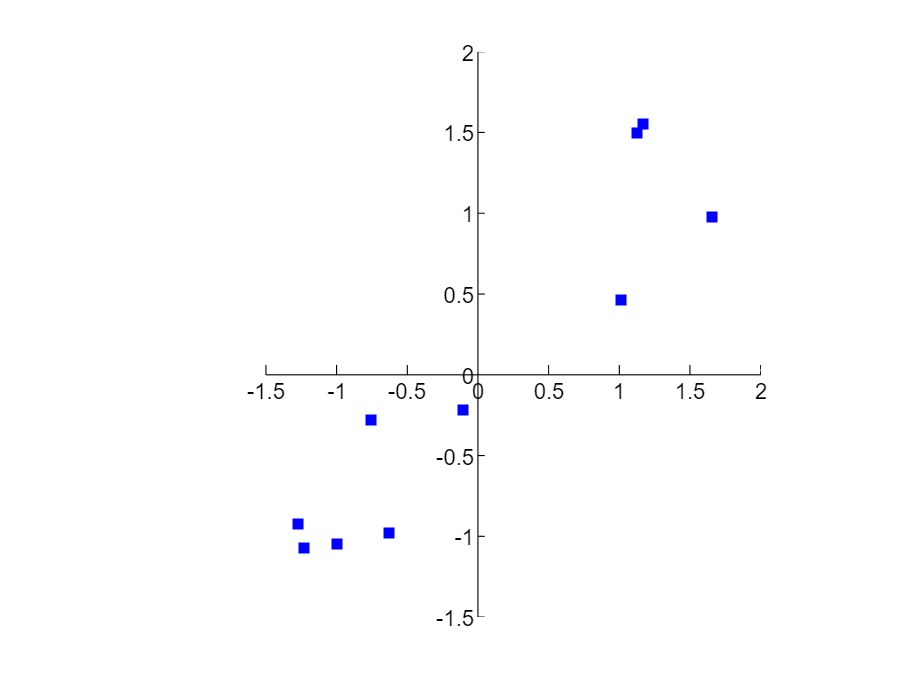

if size(X,2)>=3
	plot3(X(:,1),X(:,2),X(:,3),'sb','MarkerFaceColor',[0 0 1]);
else
	plot(X(:,1),X(:,2),'sb','MarkerFaceColor',[0 0 1]);
	fig_showaxisatorigin;
end
grid on
rotate3d on
axis square

## PCA

[PC Y V]=pca(X);
PC

PC =     0.7333   -0.6799
    0.6799    0.7333


Y

Y =    -0.7421    0.3091
   -0.2192   -0.0900
    1.9160    0.3414
   -1.1224   -0.2925
    1.0585   -0.3475
    1.8839   -0.4077
   -1.6278    0.0534
    1.8462    0.3337
   -1.4386   -0.0901
   -1.5545    0.1902


V

V =     2.3048
    0.0835


## Percent variances:

fprintf('%.2f ',V/sum(V)*100);

96.51 3.49 

### **Percent variances (cumulative):**

fprintf('%.2f ',cumsum(V)/sum(V)*100);

96.51 100.00 

## plot each PC on the original data

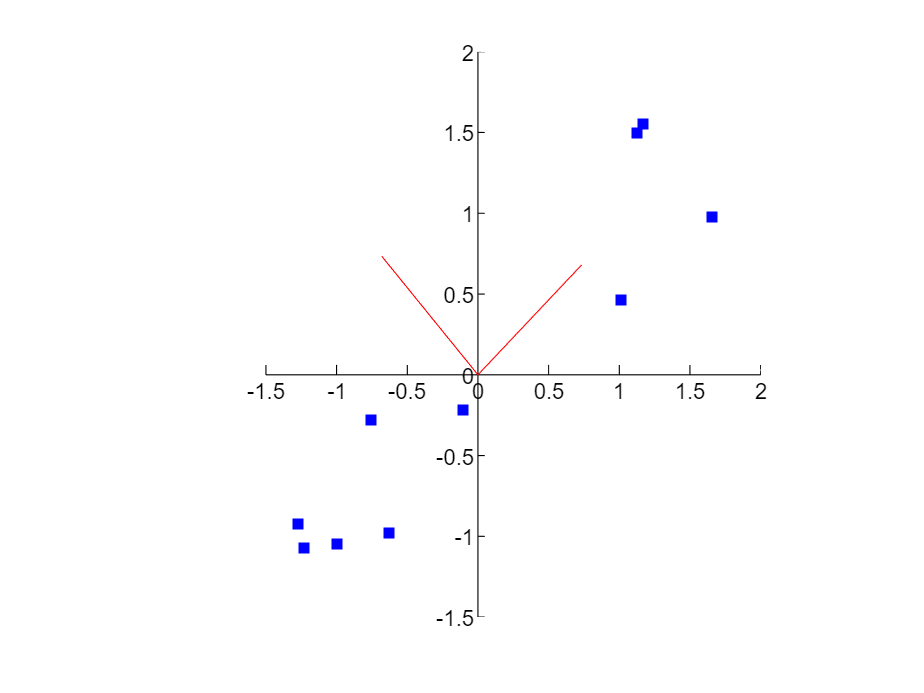

hold on
for i=1:d
	plot([0; PC(1,i)], [0; PC(2,i)], '-r');
	if i==1; hold on; end
end
hold off
axis square

## plot the projected data

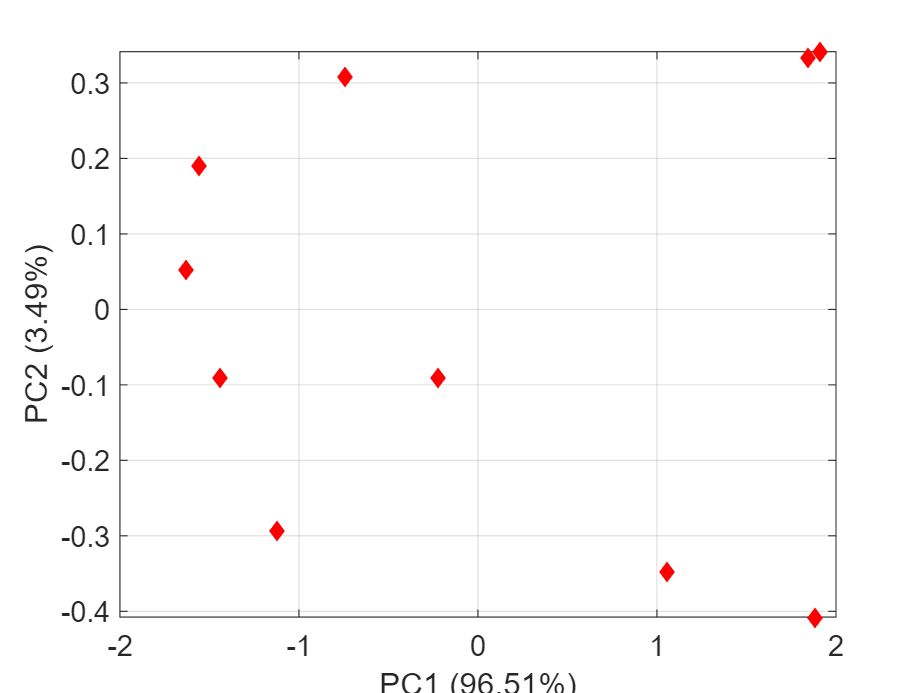

plot(Y(:,1),Y(:,2),'dr','MarkerFaceColor',[1 0 0]);
xlabel( sprintf('PC1 (%.2f%%)' , V(1)/sum(V)*100));
ylabel( sprintf('PC2 (%.2f%%)' , V(2)/sum(V)*100));
grid on

## reconstruct the data using i=1:d dimensions

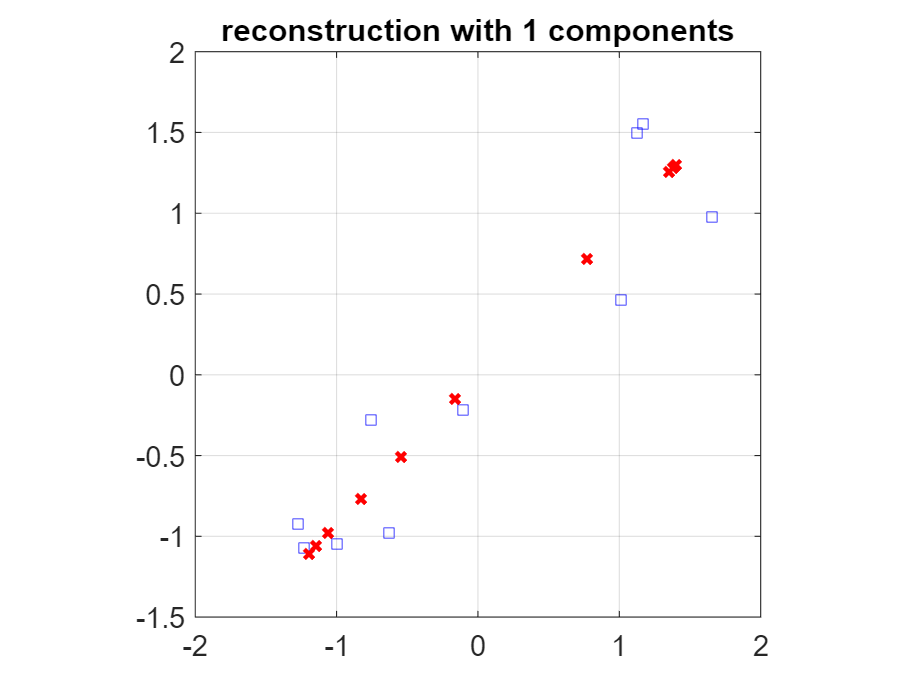

Reconstruction error using 1 components: 0.274081


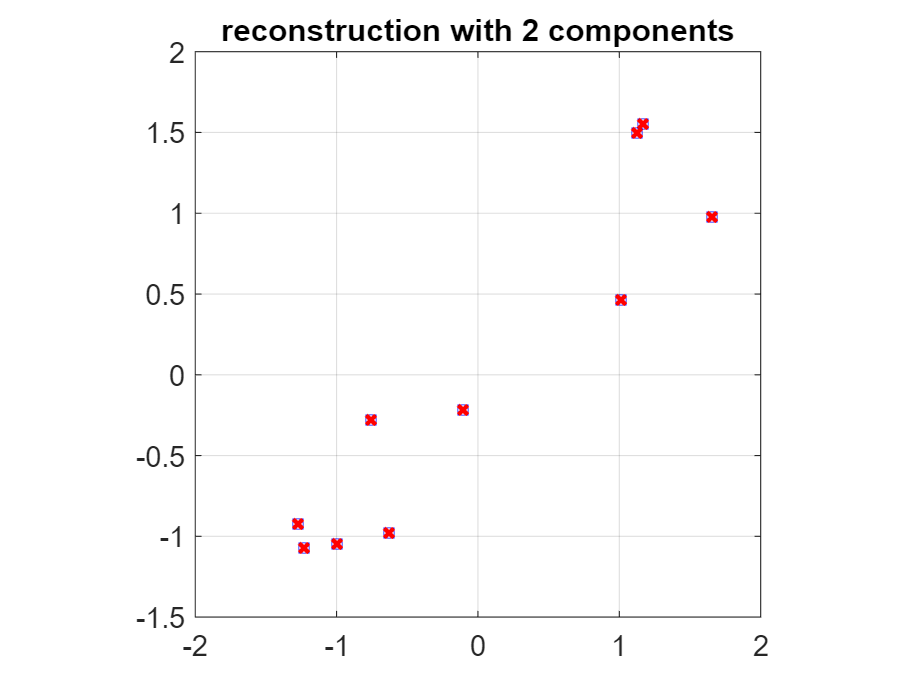

Reconstruction error using 2 components: 0.000000


for i=1:d
  Xrec = Y(:,1:i)*PC(:,1:i)';
  figure(i);
  plot(X(:,1),X(:,2),'sb');
  hold on;
  plot(Xrec(:,1),Xrec(:,2),'xr','LineWidth',2);
	hold off
  title(sprintf('reconstruction with %d components',i));
  grid on; axis square;
	% this calculation of the reconstruction error assumes X is a dataset that
	% is alredy mean-shifted.
  fprintf('Reconstruction error using %d components: %f\n',i,sqrt(mean(sum((X-Xrec).^2,2))));
  %pause;
end